% initialize
p0 = 3;
phi = 2*pi*(rand(3,1)-0.5);
A = [4, 3, 1].';
w = pi*[0.4, 0.45, 0.8].'

w =     1.2566
    1.4137
    2.5133


N = 100;

% formulate the signals
x = zeros(N,1);
for n=1:N
    for i=1:p0
        x(n) = x(n) + A(i)*exp( 1j*n*w(i) );
    end
end

% add white Gaussian noise
noise_variance = 1

noise_variance = 1

wn = sqrt(noise_variance)/sqrt(2)*( randn(N,1) + 1j*randn(N,1) );
x = x + wn;

# Pisarenko Harmonic Decomposition

p=2;
% R = corrmtx(x, p+1)
freq_est = freq_est_phd(x,p)

freq_est =     0.3910
    0.4743
    0.8606



[v_min,sigma] = phd(x,p);
v_min = v_min/norm(v_min);

% Define the frequency grid for evaluating the PHD spectrum
freq_grid = linspace(0, 1, 1024);  % Normalized frequency grid (0 to 2π)
Px_phd = zeros(size(freq_grid));   % Initialize the power spectrum

% Calculate the Pisarenko spectrum
for k = 1:length(freq_grid)
    % Create a steering vector for the current frequency
    e = exp(1j * 2 * pi * freq_grid(k) * (0:p+1)'); % steering vector
    
    % Compute the Pisarenko spectrum value at this frequency
    Px_phd(k) = 1 / abs(e' * v_min)^2;
end

% Convert to decibel scale
Px_phd = 10 * log10(abs(Px_phd));



# MUSIC Algorithm

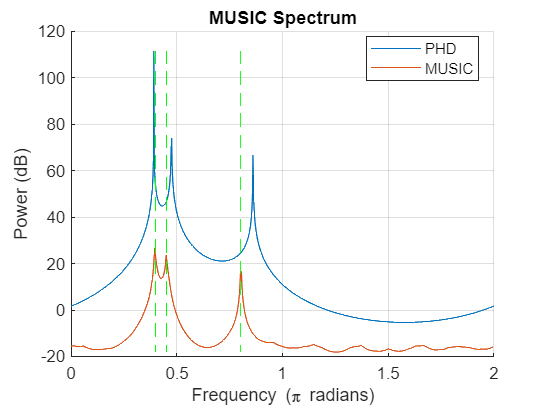

M = 10; % size of the correlation matrix
Px_music = music(x, p, M);

% get the max/min value
max_value = max(max(Px_phd), max(Px_music));
min_value = min(min(Px_phd), min(Px_music));

% Plot the estimated spectrum
freq_grid = linspace(0, 2, 1024);
figure(1); clf; hold on;
p1 = plot(freq_grid, Px_phd);
p2 = plot(freq_grid, Px_music);
plot(w(1)/pi*ones(2,1), [max_value, min_value],'g--')
plot(w(2)/pi*ones(2,1), [max_value, min_value],'g--')
plot(w(3)/pi*ones(2,1), [max_value, min_value],'g--')
legend([p1, p2], ["PHD", "MUSIC"], 'Location','best')
xlabel('Frequency (\pi radians)');
ylabel('Power (dB)');
title('MUSIC Spectrum');
grid on;